# Longitudinal Vehicle - Test Case

## RoadGrade3 - Varying Road Grade

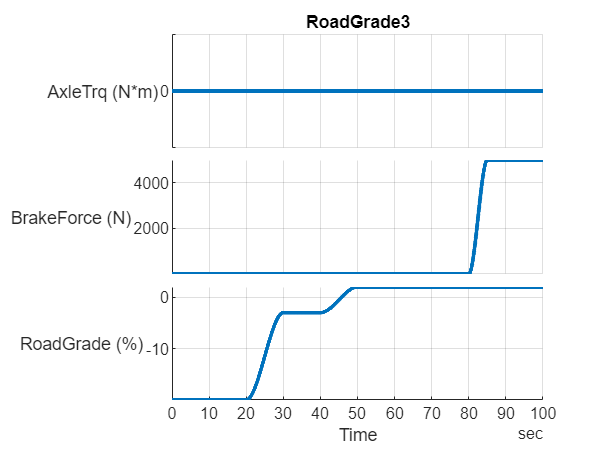

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

Vehicle1D_harness_setup

vehSigBuilder = Vehicle1D_InputSignalBuilder;
vehSigBuilder.Plot_tf = true;

inpData = RoadGrade3(vehSigBuilder, ...
            InitialVehicleSpeed_kph = 0, ...
            AxleTorque_Const_Nm = 0, ...
            RoadGrade_1_pct = -20, ...
            RoadGrade_2_pct = -3, ...
            RoadGrade_3_pct = 2, ...
            BrakeForce_1_N = 0, ...
            BrakeForce_2_N = 5000, ...
            RoadGradeChange_1_StartTime = seconds(20), ...
            RoadGradeChange_1_EndTime = seconds(20 + 10), ...
            RoadGradeChange_2_StartTime = seconds(30 + 10), ...
            RoadGradeChange_2_EndTime = seconds(40 + 10), ...
            BrakeForceChange_1_StartTime = seconds(80), ...
            BrakeForceChange_1_EndTime = seconds(80 + 5), ...
            StopTime = seconds(65 + 35) );

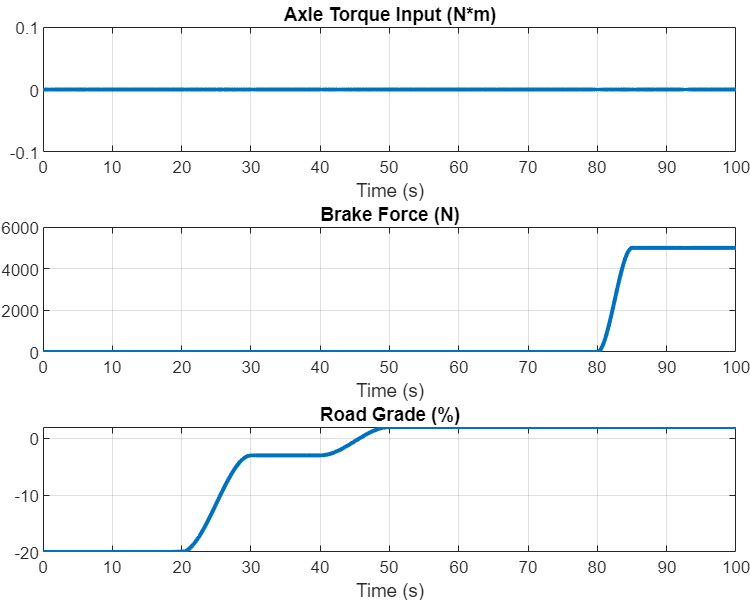

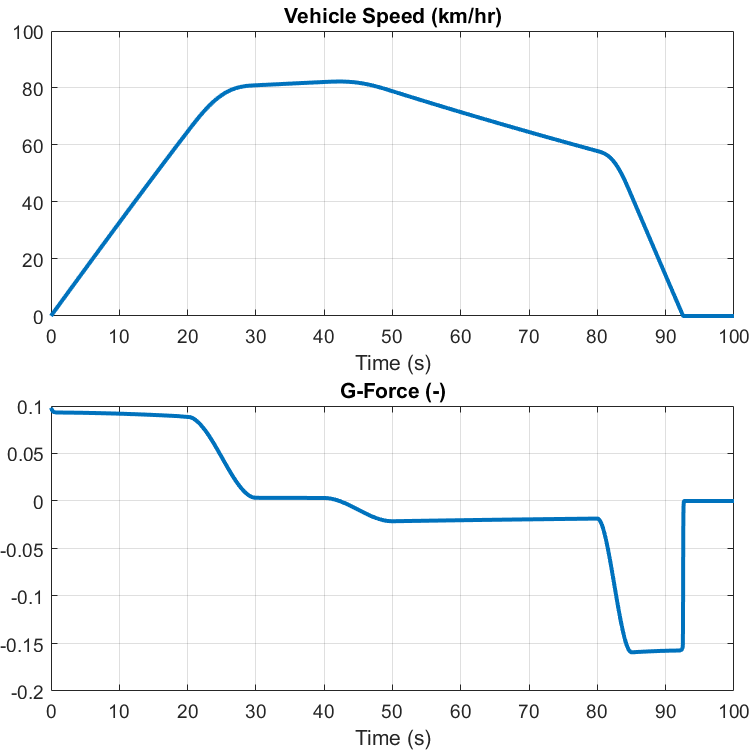

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "vehicle_InputSignals", inpData.Signals);
simIn = setVariable(simIn, "vehicle_InputBus", inpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));

v0 = inpData.Options.InitialVehicleSpeed_kph;

simIn = setBlockParameter(simIn, ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x", num2str(v0), ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_unit", "km/hr", ...
  mdl+"/Longitudinal Vehicle/Longitudinal Vehicle", "V_x_priority", "high");

simOut = sim(simIn);

Vehicle1D_plot_results(simOut.logsout);

*Copyright 2020-2022 The Mathworks, Inc.*